グラフ : Descent

[x,y] = meshgrid([200:5:300],[20000:1000:40000]);

%time, fuelの共通変数値
temp_difference = 9.561988899;
weight_time = 1.0;
weight_fuel = 1.0;
mean_time = 812.5201465;
mean_fuel = 328.868022;

%time用係数
c_cruise_altitude_time = 0.025535;
c_temp_difference_time = -3.4607;
c_descent_speed_time = -3.9502;
c_temp_difference2descent_speed_time = -0.0084471;
intercept_time = 984.22;

%fuel用係数
c_cruise_altitude_fuel = 0.0059513;
c_temp_difference_fuel = -2.7768;
c_descent_speed_fuel = 0.81042;
intercept_fuel = -81.407;

time = intercept_time ...
    + c_cruise_altitude_time .* y ...
    + c_temp_difference_time .* temp_difference ...
    + c_descent_speed_time .* x ...
    + c_temp_difference2descent_speed_time .* temp_difference .* x

time = 	1.0e+03 *

    0.6556    0.6355    0.6153    0.5952    0.5750    0.5549    0.5347    0.5146    0.4944    0.4742    0.4541    0.4339    0.4138    0.3936    0.3735    0.3533    0.3332    0.3130    0.2928    0.2727    0.2525
    0.6812    0.6610    0.6409    0.6207    0.6006    0.5804    0.5602    0.5401    0.5199    0.4998    0.4796    0.4595    0.4393    0.4192    0.3990    0.3788    0.3587    0.3385    0.3184    0.2982    0.2781
    0.7067    0.6865    0.6664    0.6462    0.6261    0.6059    0.5858    0.5656    0.5455    0.5253    0.5052    0.4850    0.4648    0.4447    0.4245    0.4044    0.3842    0.3641    0.3439    0.3238    0.3036
    0.7322    0.7121    0.6919    0.6718    0.6516    0.6315    0.6113    0.5912    0.5710    0.5508    0.5307    0.5105    0.4904    0.4702    0.4501    0.4299    0.4098    0.3896    0.3695    0.3493    0.3291
    0.7578    0.7376    0.7175    0.6973    0.6772    0.6570    0.6368    0.6167    0.5965    0.5764    0.5562    0.5361    0.5159    0.4

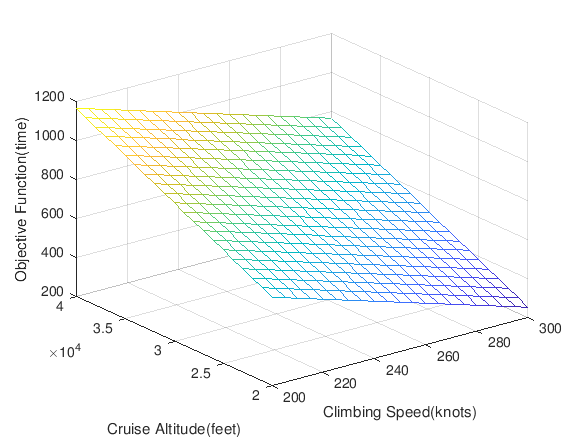

mesh(x,y,time)
xlabel('Climbing Speed(knots)')
ylabel('Cruise Altitude(feet)')
zlabel('Objective Function(time)')


fuel = intercept_fuel ...
    + c_cruise_altitude_fuel .* y ...
    + c_temp_difference_fuel .* temp_difference ...
    + c_descent_speed_fuel .* x 

fuel =   173.1513  177.2034  181.2555  185.3076  189.3597  193.4118  197.4639  201.5160  205.5681  209.6202  213.6723  217.7244  221.7765  225.8286  229.8807  233.9328  237.9849  242.0370  246.0891  250.1412  254.1933
  179.1026  183.1547  187.2068  191.2589  195.3110  199.3631  203.4152  207.4673  211.5194  215.5715  219.6236  223.6757  227.7278  231.7799  235.8320  239.8841  243.9362  247.9883  252.0404  256.0925  260.1446
  185.0539  189.1060  193.1581  197.2102  201.2623  205.3144  209.3665  213.4186  217.4707  221.5228  225.5749  229.6270  233.6791  237.7312  241.7833  245.8354  249.8875  253.9396  257.9917  262.0438  266.0959
  191.0052  195.0573  199.1094  203.1615  207.2136  211.2657  215.3178  219.3699  223.4220  227.4741  231.5262  235.5783  239.6304  243.6825  247.7346  251.7867  255.8388  259.8909  263.9430  267.9951  272.0472
  196.9565  201.0086  205.0607  209.1128  213.1649  217.2170  221.2691  225.3212  229.3733  233.4254  237.4775  241.5296  245.5817  249.6338  253.685

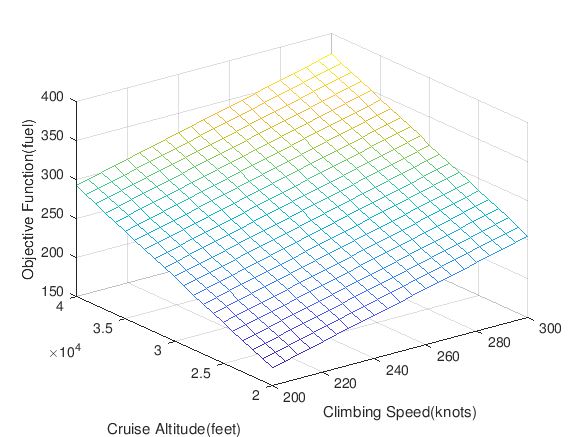


mesh(x,y,fuel)
xlabel('Climbing Speed(knots)')
ylabel('Cruise Altitude(feet)')
zlabel('Objective Function(fuel)')

time_fuel = weight_time .* time ./ mean_time + weight_fuel .* fuel ./ mean_fuel

time_fuel =     1.3334    1.3209    1.3085    1.2960    1.2835    1.2710    1.2585    1.2460    1.2335    1.2211    1.2086    1.1961    1.1836    1.1711    1.1586    1.1462    1.1337    1.1212    1.1087    1.0962    1.0837
    1.3829    1.3705    1.3580    1.3455    1.3330    1.3205    1.3080    1.2956    1.2831    1.2706    1.2581    1.2456    1.2331    1.2207    1.2082    1.1957    1.1832    1.1707    1.1582    1.1457    1.1333
    1.4325    1.4200    1.4075    1.3950    1.3825    1.3700    1.3576    1.3451    1.3326    1.3201    1.3076    1.2951    1.2827    1.2702    1.2577    1.2452    1.2327    1.2202    1.2078    1.1953    1.1828
    1.4820    1.4695    1.4570    1.4445    1.4321    1.4196    1.4071    1.3946    1.3821    1.3696    1.3572    1.3447    1.3322    1.3197    1.3072    1.2947    1.2822    1.2698    1.2573    1.2448    1.2323
    1.5315    1.5190    1.5065    1.4941    1.4816    1.4691    1.4566    1.4441    1.4316    1.4192    1.4067    1.3942    1.3817    1.3692    

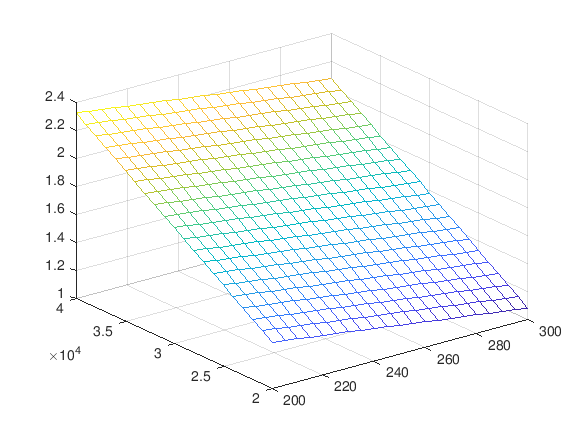

mesh(x,y,time_fuel)

xlabel('Climbing Speed(knots)')
ylabel('Cruise Altitude(feet)')
zlabel('Objective Function')